bigness=1000;
As = sin(linspace(0,50, bigness));   % A
B = sin(linspace(0,37, bigness)+5); % B
%C = sin(linspace(0,45, bigness)+2)


M1 = As - 2*B; % + 4*C;                  % mixing 1
M2 = 1.73*As+3.41*B; % - C;            % mixing 2
%M3 = As - B + C;

M = [M1;M2];



[Mw, whiteningMatrix, dewhiteningMatrix, means] = preprocessing(M);

[A, W] = icaRounds(whiteningMatrix, dewhiteningMatrix, Mw, means);

icasig = W * M + (W * means) * ones(1, bigness);


% clf
% 
% subplot(3,3,1)
% plot(As);
% 
% subplot(3,3,2)
% plot(B);
% 
% subplot(3,3,3)
% plot(C);
% 
% subplot(3,3,4)
% plot(M1);
% 
% subplot(3,3,5)
% plot(M2);
% 
% subplot(3,3,6)
% plot(M3);
% 
% subplot(3,3,7)
% plot(icasig(1,:));
% 
% subplot(3,3,8)
% plot(icasig(2,:))
% 
% subplot(3,3,9)
% plot(icasig(3,:))

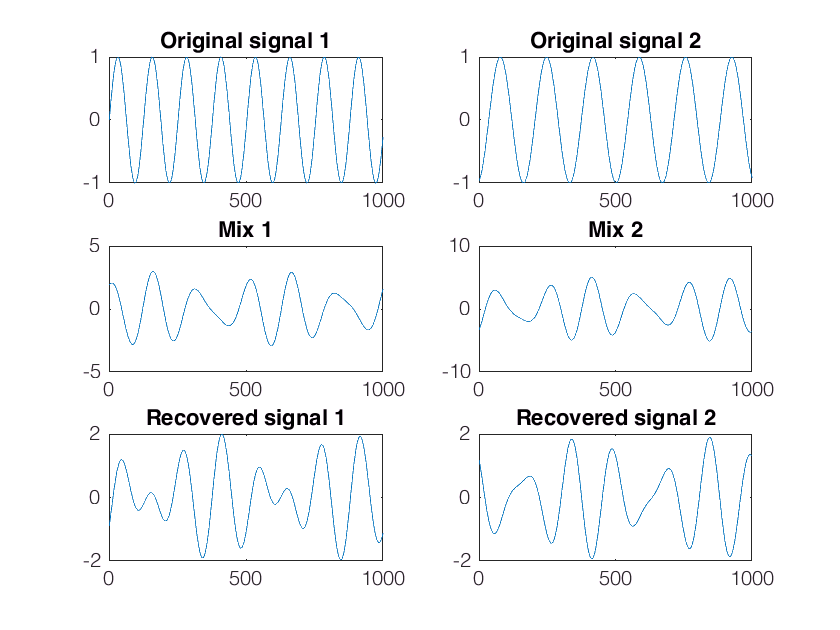

clf

subplot(3,2,1)
plot(As);
title('Original signal 1')

subplot(3,2,2)
plot(B);
title('Original signal 2')

subplot(3,2,3)
plot(M1);
title('Mix 1')

subplot(3,2,4)
plot(M2);
title('Mix 2')

subplot(3,2,5)
plot(icasig(1,:));
title('Recovered signal 1')

subplot(3,2,6)
plot(icasig(2,:))
title('Recovered signal 2')